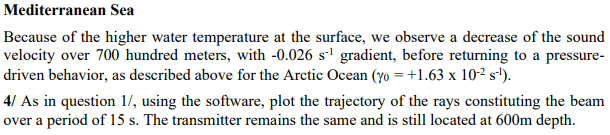

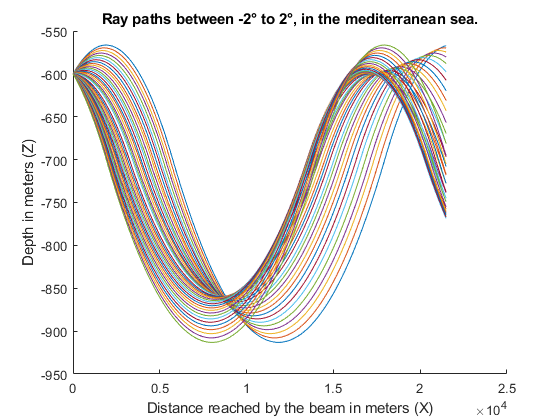

clear
clc
% Initial conditions
Co = 1450;
h = 3500 ; % Depth Seafloor
z_inv = 700;
gamma_0 = -0.026;
gamma_1 = 1.63e-2;

% Parameter difinition
zs = 600;
total_period = 15; %Total time in seconds
dt = 0.01;
t = 0:dt:total_period;

% The defines the range of the angles to be analyzed
angle = -2:0.1:2;
angle = angle(angle ~= 0);
% angle = [-2 2]

% Defines a Matrix which is going to contain the depth reached for the given
% sampling time
n_rows = length(angle);
n_columns = length(t);

ray_matrix = zeros(n_rows, n_columns);


for i = 1:length(angle)
    
    x = zeros(size(t));
    x(1) = 0;
    
    z = zeros(size(t));
    z(1) = zs;
    
    theta = zeros(size(t));
    theta(1)  = angle(i)*pi/180;
    
    c = zeros(size(t));
    c(1)=velocity(z(1), z_inv, Co, gamma_0, gamma_1 );
    
    ray_matrix(:,1) = z(1);
    
    for j = 2:length(t)
        
        % Calculates the distance traveled
        x(j) = x(j-1) + c(j-1) * dt * cos(theta(j-1));
        % Calculates the depth reached
        z(j) = z(j-1) + c(j-1) * dt * sin(theta(j-1));
        % Calculates the speed reached
        c(j) = velocity(z(j), z_inv, Co, gamma_0, gamma_1 );
        
        % Verifies the value of the Snell constant
        K = cos(theta(j-1))*c(j)/c(j-1);
        
        if K <= 1
            
            theta(j) = sign(theta(j-1))*acos(K);
            
        else
    
            z(j) = z(j-1);
            c(j) = c(j-2);
            theta(j) = -theta(j-2);
            
        end
        
        % Flips the ray in case that reach the surface or the max depth
        if (z(j) <= 0) || (z(j)>=h)
            
            z(j) = z(j-1);
            c(j) = c(j-2);
            theta(j) = -theta(j-2);
            
        end   
        % stores the value of the depth reached
        ray_matrix(i,j) =  z(j);
        
    end
    figure(1)
    hold on
    plot(x,-ray_matrix(i,:))
    
end

title('Ray paths between -2° to 2°, in the mediterranean sea.')
xlabel('Distance reached by the beam in meters (X)') 
ylabel('Depth in meters (Z)') 

hold off

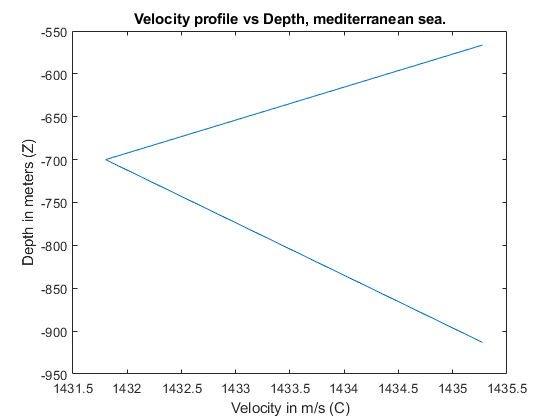

figure(2)
plot(c,-ray_matrix(end,:))
title('Velocity profile vs Depth, mediterranean sea.')
xlabel('Velocity in m/s (C)' ) 
ylabel('Depth in meters (Z)') 

% Gives the position in the x vector which gives a distance >= 10000m
position_10_km = find(x>=10000, 1,'first')

position_10_km = 699

% uses the ray_matrix to get the min the depth at 10000m
min_distance = min(ray_matrix(:,position_10_km))

min_distance = 844.3912

% uses the ray_matrix to get the max the depth at 10000m
max_distance = max(ray_matrix(:,position_10_km))

max_distance = 893.4646

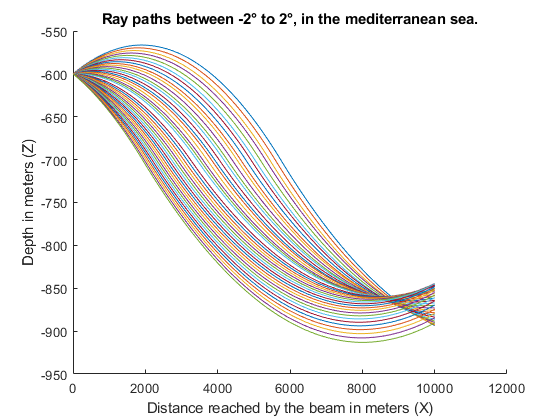

% Draw of the transmitter' paths to reach 10000m
figure(3)
for i=1:length(angle)
    hold on
    plot(x(1:position_10_km),-ray_matrix(i,1:position_10_km))
end

title('Ray paths between -2° to 2°, in the mediterranean sea.')
xlabel('Distance reached by the beam in meters (X)') 
ylabel('Depth in meters (Z)') 

function c = velocity(z, z_inv, Co, gamma_0, gamma_1 )
    
    if z<z_inv
        c = gamma_0 * z + Co;
    else
        c_inv = gamma_0*z_inv + Co;
        b = c_inv - gamma_1*z_inv;
        c = gamma_1*z + b;
    end
    
end